# Skin Lesion Classification Using Pretrained Network and Transfer Learning

**by cclay6 and BiancaPhil**

Objective:

This project will showcase the methodolgy to create and train a simple convolutional neural network for deep learning classification using a pretrained network called alexnet and transfer learning. The classifiers produced will distinguish between benign and malignant skin lesion images. Then, the classifiers will be applied to pristine, noisy, and denoised skin lesion images.

## Load Skin Lesion Image Data

Load the skin lesion images data as an image datastore. The `imageDatastore `has the ability to automatically labels the images based on folder names.

% The file path was adjusted to obtain the skin lesion images.
imageFolder = './';

%creates image data store object containing benign and malignant skin lesions
imds = imageDatastore(imageFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imds.ReadFcn = @(filename)readAndPreprocessImage(filename); %preprocesses data to be the size that alexnet expects

## Analyze Dataset Distribution and Input Data Size

Calculate the number of images in each category. If there are different number of images per category, it means the dataset is imbalanced.

labelCount = countEachLabel(imds)

labelCount = 2×2 table
      Label      Count
    _________    _____

    benign       8924 
    malignant    1115 


This is some code to clean up the dataset to make it balanced. We chose to have 200 benign images and 200 malignant images to achieve this balance and also to reduce neural network training times.

% Determine the smallest amount of images in a category
minSetCount = min(labelCount{:,2}); 

% Limited the number of images 
maxNumImages = 200;
minSetCount = min(maxNumImages,minSetCount);

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Each set contain the same number of images.
countEachLabel(imds)

ans = 2×2 table
      Label      Count
    _________    _____

    benign        200 
    malignant     200 


## Present Data

Display some of the images in the datastore.

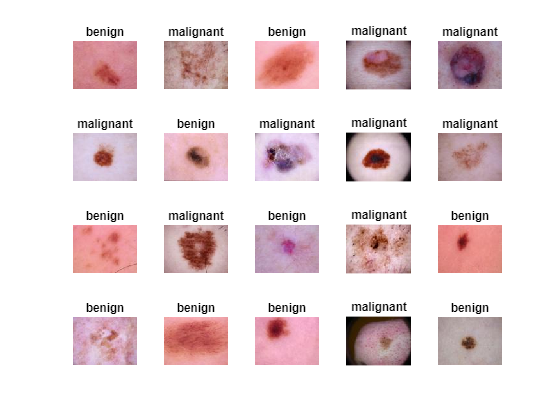

%The data and images are displayed
figure;
perm = randperm(400,20);
for i = 1:20
    subplot(4,5,i); %4x5 matrix
    imshow(imds.Files{perm(i)}), title(imds.Labels(perm(i)))%added description to the display of the images
end

## Specify Training and Validation Sets

Divide the data into training and validation data sets, so that each category in the training set contains a large percentage of the images, and the validation set contains the remaining images from each label. `splitEachLabel` splits the image datastore into two new datastores for training and validation.

percentageTrainingFiles = 0.85; % Using 85% for training, 15% for validation
[imdsTrain,imdsValidation] = splitEachLabel(imds,percentageTrainingFiles);

rng(42); % Random number generator  (to ensure reproducibility)

## Define Network Architecture and Image Augmentation Options

Defines the convolutional neural network architecture and some image augmentation options. This section will involve a pretained alexnet neural network and transfer learning where only the last three layers are trained. We decided on this approach since the architecture made from scratch had poor classification performance, as the accuracy rate was at 55%.

model1= alexnet; %loads pretrained alexnet network
inputSize = model1.Layers(1).InputSize;

imageAugmenter = imageDataAugmenter( ...  %implemented the imageAugmenter function to add variety to dataset
    'RandRotation',[0,90], ...
    'RandXTranslation',[-5 5], ...
    'RandScale', [0.8 1.2], ...
    'RandYTranslation',[-5 5]);

imdsTrainAug = augmentedImageDatastore(inputSize,imdsTrain, 'DataAugmentation', imageAugmenter);
imdsValidationAug = augmentedImageDatastore(inputSize, imdsValidation);

numClasses = numel(categories(imdsTrain.Labels)); %categorized the classes that includes the labels 


layersTransfer = model1.Layers(1:end-3); %copies all layers except for the last three layers

%sets up the layers of the alexnet network

layers = [     %description of the layers
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];


## Specify Training Options 

options = trainingOptions('sgdm', ...       %parameters of network training options
    'MiniBatchSize',10, ... 
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidationAug, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train Neural Network

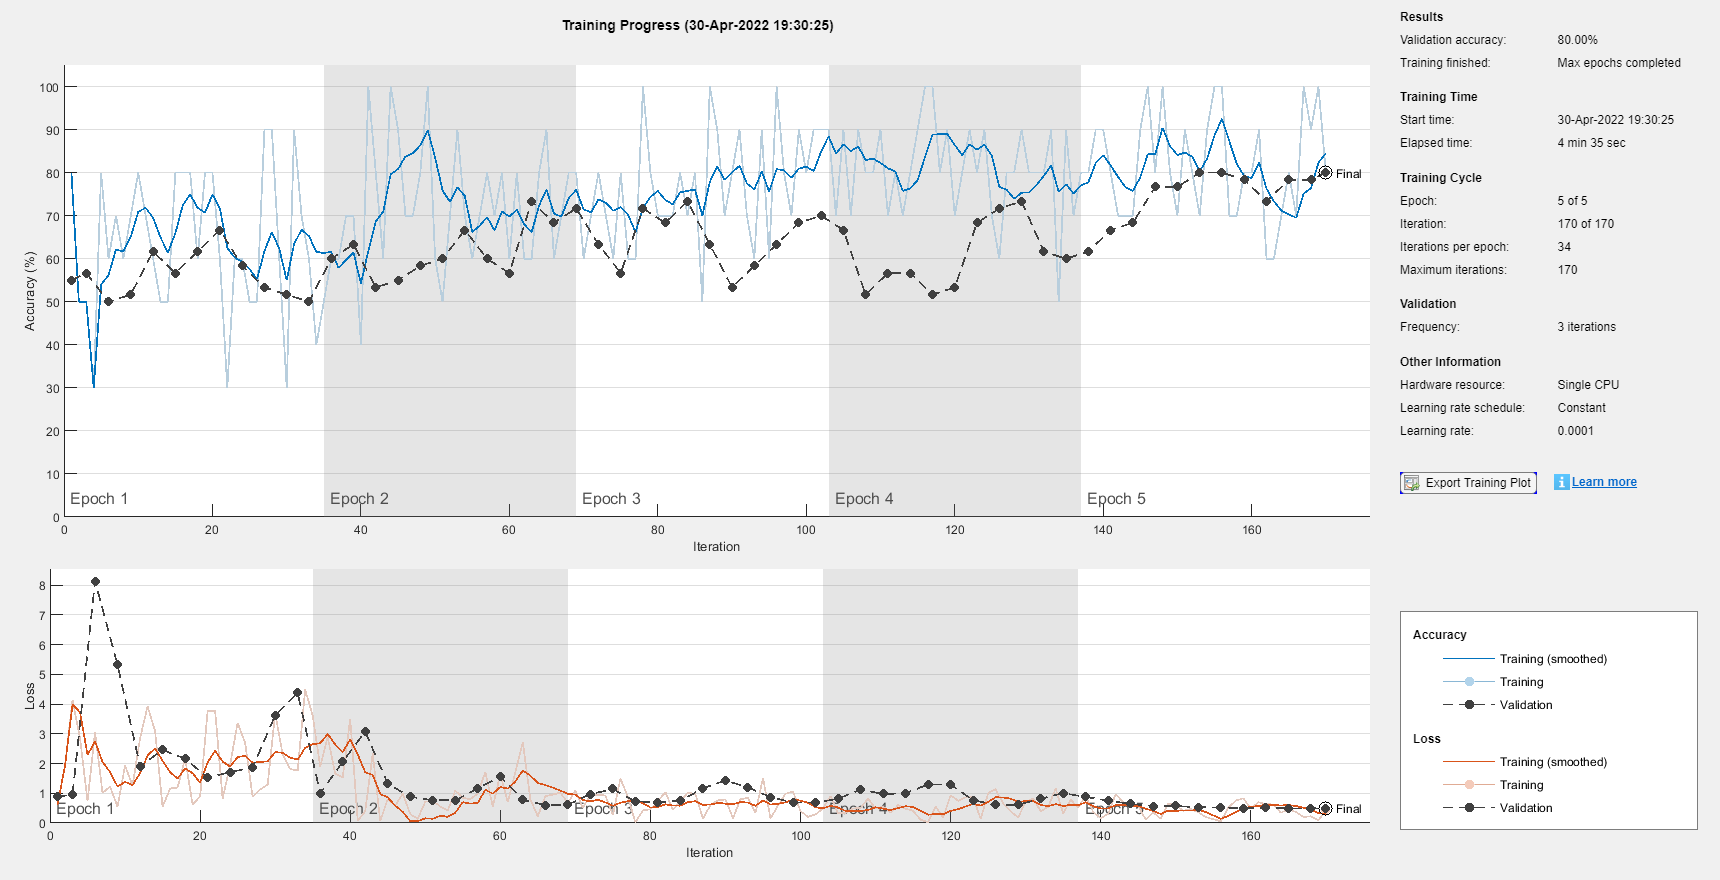

%trains last three layers of alexnet network according to first set of image augmentation and training options
model2= trainNetwork(imdsTrainAug,layers,options);

## Classify validation Images

Classify the validation images.

[YPred,scores] = classify(model2,imdsValidationAug);
YValidation = imdsValidation.Labels; %validation that includes the labels

Display four sample validation images with their predicted labels.

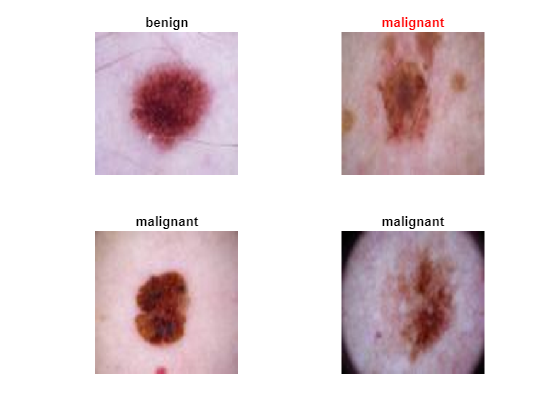

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)   %2x2 matrix 
    I = readimage(imdsValidation,idx(i));
    imshow(I)     %displaying the image 
    label = YPred(idx(i));
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');   %adding qualitative description to the images
    else
        title(string(label), 'Color','red');
    end
end

## Evaluate Performance

### Meaure the classification accuracy. 

YPred = classify(model2,imdsValidationAug);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation) %measuring the accuracy of the validated images

accuracy = 0.8000

### Showcase confusion matrix

The main objective of the skin lesion classifier is to reduce the number

of malignant images that are being classfied as benign. This is vital

in medicine, as ignoring care of malignant lesion due to it being classified as benign could be deterimental

or even deadly. In addition, the second main objective is to obtain a balanced number of benign images being classfied as malignant. 

This would aid in decreasing the number of unnecessary biopsies and procedures.

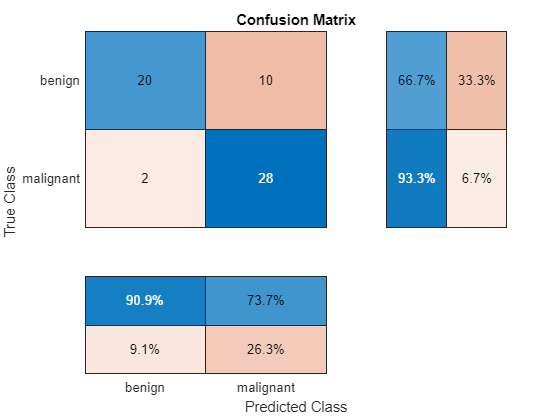

figure  %display the confusion matrix
cm = confusionchart(YValidation,YPred);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Confusion Matrix';

## Train Network with Different Image Augmentation and Training Options

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter2 = imageDataAugmenter( ...   %implement geometric configurations of the imageAugmenter 
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
imdsTrainAug2 = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter2);

imdsValidationAug2 = augmentedImageDatastore(inputSize(1:2),imdsValidation);

options2 = trainingOptions('sgdm', ...     %training parameters
    'MiniBatchSize',10, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',imdsValidationAug2, ...
    'Verbose',false, ...
    'Plots','training-progress');

**Train Network**

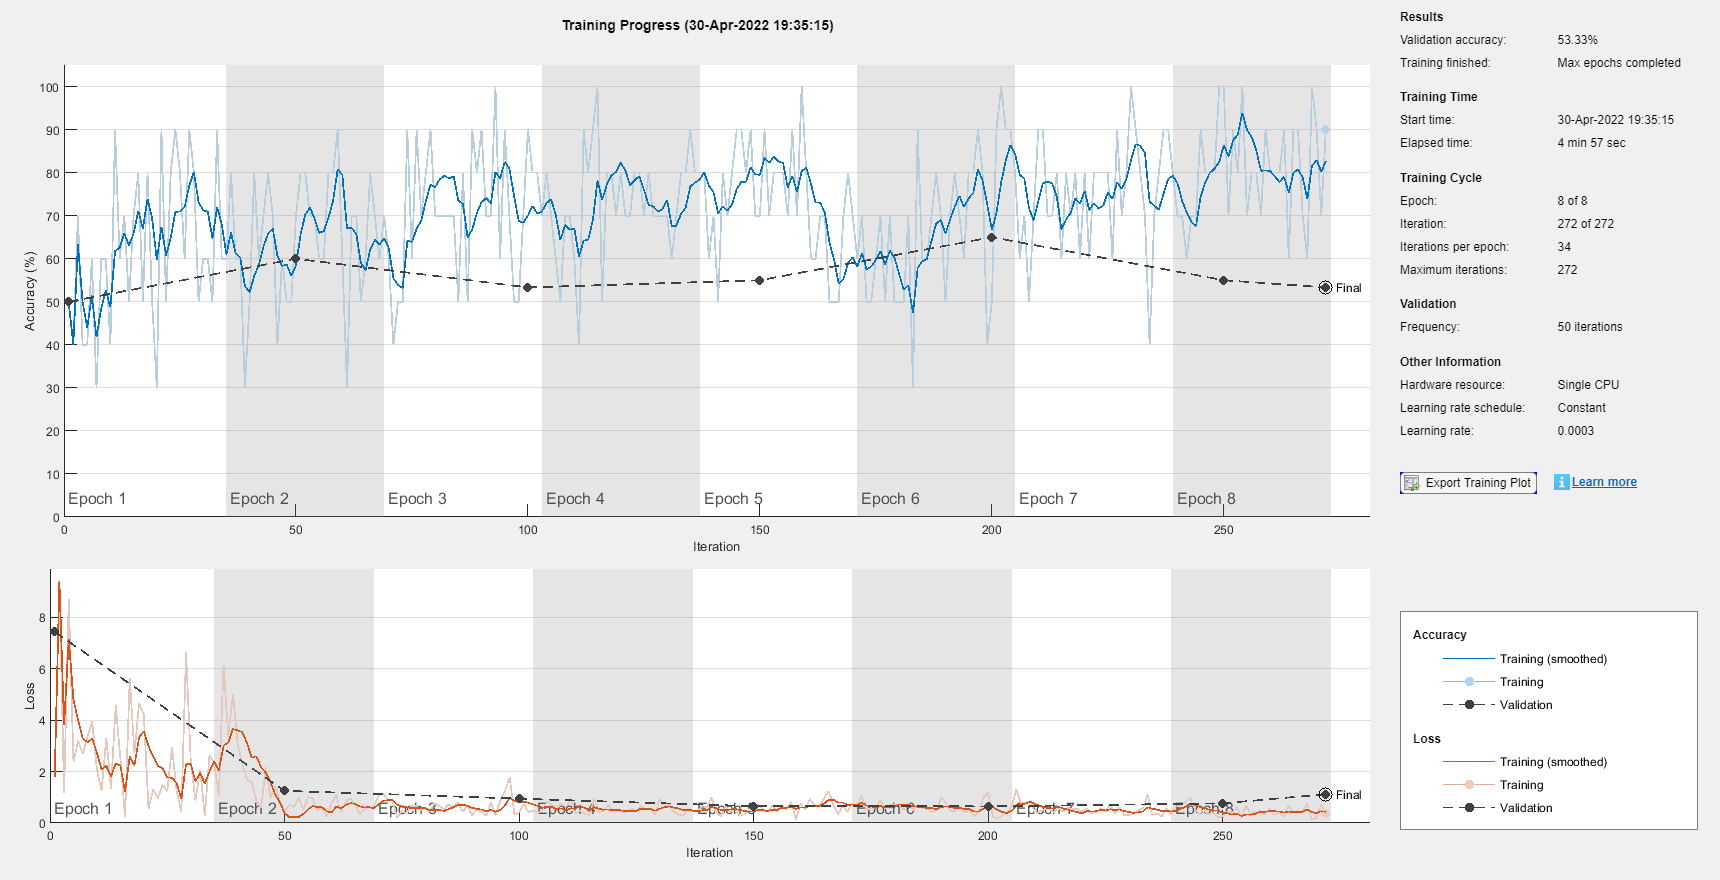

%trains last three layers of alexnet network according to second set of image augmentation and training options 
model3= trainNetwork(imdsTrainAug2,layers,options2);

## Evaluate Performance of Network with Different Augmentation and Training Options

### Calculate the Classification Accuracy

YPred2 = classify(model3,imdsValidationAug2);
YValidation2 = imdsValidation.Labels;

accuracy2 = sum(YPred2 == YValidation2)/numel(YValidation2)  %equation for accuracy for validation set 2

accuracy2 = 0.5333

### Showcase confusion matrix

The main objective of the skin lesion classifier is to reduce the number

of malignant images that are being classfied as benign. This is vital

in medicine, as ignoring care of malignant lesion due to it being classified as benign could be deterimental

or even deadly. In addition, the second main objective is to obtain a balanced number of benign images being classfied as malignant. 

This would aid in decreasing the number of unnecessary biopsies and procedures.

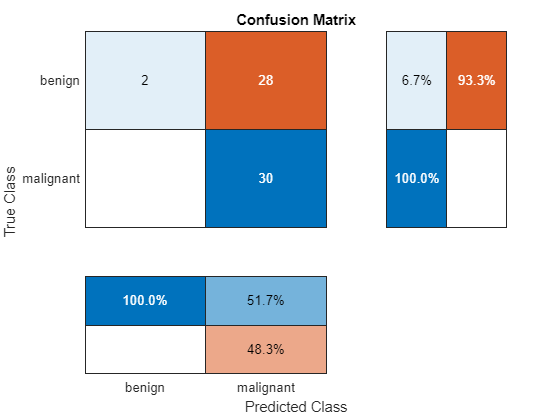

figure   %displaying the confusion matrix
cm2 = confusionchart(YValidation2,YPred2);
cm2.ColumnSummary = 'column-normalized';
cm2.RowSummary = 'row-normalized';
cm2.Title = 'Confusion Matrix';

## Create Noisy Dataset

We ran into a dead end. The classify function used by the CNN seems to not accept transform image datastore objects or denoising image datastore objects. We also attempted to write the noisy image files to the disk and create a new image datastore object that could be used by the classifier, but the writeall function did not work like what the documentation specified, where we got an error that said "OutputFormat" or "WriteFcn" must be specified when calling "writeall" on this datastore. 

Our intent was to create a noisy data set and use the classifier we trained to see the effect on classification performance.

% add noise to dataset
noisy_imdsValidation = transform(imdsValidation,@addNoise);
%Preprocesses images in datastore to be the size that alexnet expects
noisy_imdsValidation = transform(imdsValidation,@changeSize);
%writeall(noisy_imdsValidation, 'C:\noisyOutput');
%noisy_imdsValidation= denoisingImageDatastore(imdsValidation);
%noisy_imdsValidation = transform(imdsValidation,@changeSize); %Preprocesses images in datastore to be the size that alexnet expects

## Create Denoised Dataset

Similarly, we ran into a deadend with creating a denoised dataset for the same reason that using the noisy dataset did not work: the classify function would not accept a transformed data image store object. We presumed that the classifier would perform better on a denoised dataset and worse for a noisy dataset.

%remove noise from dataset
denoised_imdsValidation = transform(noisy_imdsValidation,@removeNoise);
%Preprocesses images in datastore to be the size that alexnet expects
denoised_imdsValidation = transform(denoised_imdsValidation,@changeSize);

## Classify Noisy Dataset and Evaluate Classification Performance

Nonfunctioning.

### Calculate the Classification Accuracy

%YPred_noisy = classify(model2,noisy_imdsValidation);
%YValidation_noisy = imdsValidation.Labels;
%accuracy_noisy = sum(YPred_noisy == YValidation_noisy)/numel(YValidation_noisy)

### Showcase confusion matrix

%figure
%cm_noisy = confusionchart(YValidation_noisy,YPred_noisy);
%cm_noisy.ColumnSummary = 'column-normalized';
%cm_noisy.RowSummary = 'row-normalized';
%cm_noisy.Title = 'Confusion Matrix';

## Classify Denoised Dataset and Evaluate Classification Performance

Nonfunctioning

### Calculate the Classification Accuracy

%YPred_denoised = classify(model2,denoised_imdsValidation);
%YValidation_denoised = imdsValidation.Labels;
%accuracy_denoised = sum(YPred_denoised == YValidation_denoised)/numel(YValidation_denoised)

### Showcase confusion matrix

%figure
%cm_denoised = confusionchart(YValidation_denoised,YPred_denoised);
%cm_denoised.ColumnSummary = 'column-normalized';
%cm_denoised.RowSummary = 'row-normalized';
%cm_denoised.Title = 'Confusion Matrix';

## Classify Pristine, Noisy, and Denoised Images

Since we were unable to classify an entire dataset of noisy and denoised images, we decided to classify individual pristine, noisy, and denoised images (one benign and one malignant) to observe the prediction results of both classifiers (model 2 and model 3, which had slightly different augmentation and training options). We predict that there will be poor results for classifying noisy images and perhaps better results for denoised images.

### Benign Skin Lesion Image

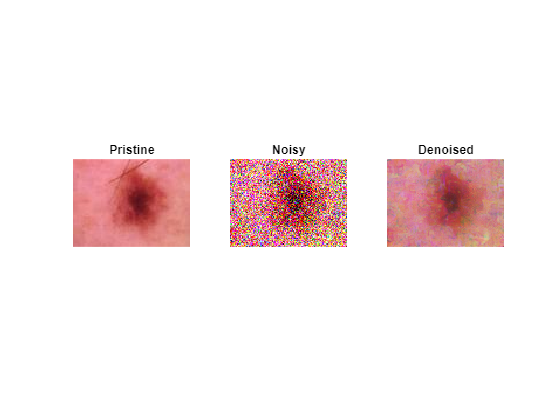

I=imread('benign\ISIC_0024306.jpg'); %read benign image

%add noise to benign image
I2= im2double(I);
I2=imnoise(I, 'gaussian', 0,0.1);

%remove noise from benign image
% Split the noisy benign image into its individual color channels
noisyRGB= I2;
[noisyR,noisyG,noisyB] = imsplit(noisyRGB);

% Load the pretrained DnCNN network
preTrainedDnCNN = denoisingNetwork('dncnn');

% Use the DnCNN network to remove noise from each color channel
denoisedR = denoiseImage(noisyR,preTrainedDnCNN);
denoisedG = denoiseImage(noisyG,preTrainedDnCNN);
denoisedB = denoiseImage(noisyB,preTrainedDnCNN);

% Recombine the denoised color channels to form the denoised RGB image
denoisedBenign = cat(3,denoisedR,denoisedG,denoisedB);

%show pristine, noisy, and denoised benign images
figure
subplot(1,3,1), imshow(I), title('Pristine')
subplot(1,3,2), imshow(I2), title('Noisy')
subplot(1,3,3), imshow(denoisedBenign), title('Denoised')

I= imresize(I, [227, 227]); %resize pristine benign image for alexnet input
I2= imresize(I2, [227, 227]); %resize noisy benign image for alexnet input
denoisedBenign= imresize(denoisedBenign, [227,227]); %resize denoised benign image for alexnet input
YPred = classify(model2,I)  %predict category of pristine benign image using model 2 classifier

YPred = categorical
     benign 


YPred= classify(model2,I2) %predict category of noisy benign image using model 2 classifier

YPred = categorical
     benign 


YPred= classify(model2,denoisedBenign) %predict category of denoised benign image using model 2 classifier

YPred = categorical
     benign 


YPred= classify(model3,I) %predict category of pristine benign image using model 3 classifier

YPred = categorical
     benign 


YPred= classify(model3,I2) %predict category of noisy benign image using model 3 classifier

YPred = categorical
     benign 


YPred= classify(model3,denoisedBenign) %predict category of denoised benign image using model 3 classifier

YPred = categorical
     malignant 


### Malignant Skin Lesion Image

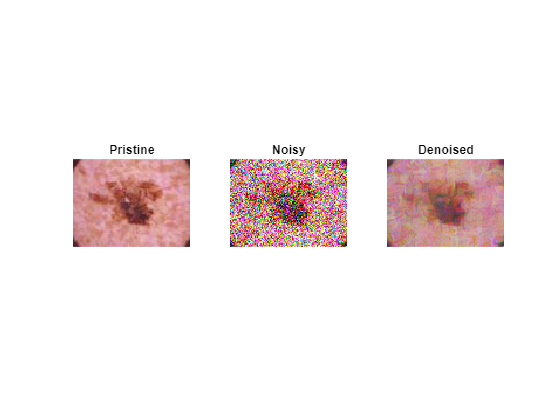

I3=imread('malignant\ISIC_0024310.jpg'); %read malignant image

%add noise to malignant image
I4= im2double(I3);
I4= imnoise(I4, 'gaussian', 0,0.1);

%remove noise from malignant image
% Split the noisy benign image into its individual color channels
noisyRGB= I4;
[noisyR,noisyG,noisyB] = imsplit(noisyRGB);

% Load the pretrained DnCNN network
preTrainedDnCNN = denoisingNetwork('dncnn');

% Use the DnCNN network to remove noise from each color channel
denoisedR = denoiseImage(noisyR,preTrainedDnCNN);
denoisedG = denoiseImage(noisyG,preTrainedDnCNN);
denoisedB = denoiseImage(noisyB,preTrainedDnCNN);

% Recombine the denoised color channels to form the denoised RGB image
denoisedMalignant = cat(3,denoisedR,denoisedG,denoisedB);

%show pristine, noisy, and denoised malignant images
figure
subplot(1,3,1), imshow(I3), title('Pristine')
subplot(1,3,2), imshow(I4), title('Noisy')
subplot(1,3,3), imshow(denoisedMalignant), title('Denoised')

I3= imresize(I3, [227, 227]); %resize pristine malignant image for alexnet input
I4= imresize(I4, [227, 227]); %resize noisy malignant image for alexnet input
denoisedMalignant= imresize(denoisedMalignant, [227, 227]); %resize denoised malignant image for alexnet input
YPred = classify(model2,I3)  %predict category of pristine malignant image using model2 classifier

YPred = categorical
     malignant 


YPred= classify(model2,I4) %predict category of noisy malignant image using model 2 classifier

YPred = categorical
     benign 


YPred= classify(model2,denoisedMalignant) %predict category of denoised malignant image using model 2 classifier

YPred = categorical
     benign 


YPred= classify(model3,I3) %predict category of pristine malignant image using model 3 classifier

YPred = categorical
     malignant 


YPred= classify(model3,I4) %predict category of noisy malignant image using model 3 classifier

YPred = categorical
     benign 


YPred= classify(model3,denoisedMalignant) %predict category of denoised malignant image using model 3 classifier

YPred = categorical
     benign 


%helper function

function dataOut = addNoise(data) %adds noise to every image in the datastore object
    dataOut = data;
    for idx = 1:size(data,1)
       dataOut{idx} = imnoise(data{idx},'gaussian',0,0.1);
    end
end

%changes size of images in a image datastore object to match the size
%expected by alexnet network
function dataOut = changeSize(data)
    dataOut= data;
    for idx = 1:size(data,1)
        I= imread(data{idx});
        if ismatrix(I)
            I= cat(3,I,I);
        end
       dataOut{idx}= imresize(I, [227, 227]);
    end

end

%denoises every image in a image datastore object
function dataOut = removeNoise(data)
    dataOut = data;
    for idx = 1:size(data,1)
        % Load RGB image
        pristineRGB = imread(data{idx});
        % Convert to double
        pristineRGB = im2double(pristineRGB);
        % Add Gaussian noise
        noisyGaussianRGB = imnoise(pristineRGB,'gaussian',0,0.01);

        % Split the Gaussian noisy RGB image into its individual color channels.
        [noisyGaussianR,noisyGaussianG,noisyGaussianB] = imsplit(noisyGaussianRGB);

        % Use the DnCNN network to remove Gaussian noise from each color channel
        denoisedGaussianR = denoiseImage(noisyGaussianR,preTrainedDnCNN);
        denoisedGaussianG = denoiseImage(noisyGaussianG,preTrainedDnCNN);
        denoisedGaussianB = denoiseImage(noisyGaussianB,preTrainedDnCNN);


        % Recombine the denoised Gaussian color channels to form the denoised RGB image
        denoisedGaussianRGB = cat(3,denoisedGaussianR,denoisedGaussianG,denoisedGaussianB);

        %Replaces noisy image in datastore with denoised image

        dataOut{idx} = denoisedGaussianRGB;
    end
end
